clear all;
clc;

L = 130e-6;
dsl = 0.625;
dso = 0;
no_st_turns= 4;
no_rt_turns = 20;
r = 0.0642;
g0 = 1.6e-3;
i=1;
j=1;

data_size =200;
h_size = 200;
gamma = ((11*pi)/180);
theta_r = linspace(0, 2*pi, data_size);
phi = linspace(0, 2*pi, data_size);
z = linspace(0, L, data_size);
d = 0.3;

mu_0 = 4* pi* 10e-7;

r_t_for_theta = zeros(data_size, data_size);
r_w_for_theta = zeros(data_size, data_size);
s_w = zeros(data_size, data_size);

Lxy_for_theta = zeros( data_size, 6,  6);
Lxy_mat = zeros(6, 6, data_size, data_size);
k = data_size;
dz = L / k;
z_midpoints = linspace(dz/2, L-dz/2, k);
G_for_z = zeros(data_size, data_size);

turns_phases = cell(2, 3);
winding_phases = cell(2, 3);

for phase = 1:3
    turns_phases{1, phase} = zeros(1, data_size);
    turns_phases{2, phase} = zeros(data_size, data_size);
    winding_phases{1, phase} = zeros(data_size, data_size);
    winding_phases{2, phase} = zeros(data_size, data_size);
end

% Calculate stator Turns
% Stator Turns function is calculated for every phase
% This does not depened on theta or z so we calculate it outside the loops.
for phase = 1:3
    turns_phases{1, phase} = stator_turns(phi, h_size, phase, no_st_turns);
end


for t_i = 1:data_size
    % Rotor turns function
    for phase = 1:3
        turns_phases{2, phase}(t_i, :) = rotor_turns(phi, theta_r(t_i), no_rt_turns, phase, h_size);
    end

    %Initialize arrays for EACH PHASE
    [s_w_temp, r_w_temp, L_yx_temp, int_n_over_g_sum_s, g_avg_sum_s, int_n_over_g_sum_r, g_avg_sum_r] = initialize_arrays();


    for i_z = 1: data_size
        % Calculate Air Gap function
        d_z = (((dsl-dso)/L)*dz*i_z)+(dso);
        G = g0 * (1 - (d_z .* cos(phi)));
        G_for_z(:, i_z)= G;
        
        % Calculate Winding function for each phase, for stator and rotor
        for phase = 1:3
            [s_w_temp(phase), int_n_over_g_sum_s(phase), g_avg_sum_s(phase)] = winding_function(turns_phases{1, phase}, G, phi, dz, L, g_avg_sum_s(phase), int_n_over_g_sum_s(phase));
            winding_phases{1, phase}(:, i_z) = turns_phases{1, phase} - s_w_temp(phase);
            [r_w_temp(phase), int_n_over_g_sum_r(phase), g_avg_sum_r(phase)] = winding_function(turns_phases{2, phase}(t_i, :), G, phi, dz, L, g_avg_sum_r(phase), int_n_over_g_sum_r(phase));
            winding_phases{2, phase}(t_i, :) = turns_phases{2, phase}(t_i, :) - r_w_temp(phase);
        end
        for i = 1:6
            for j = 1:6
                [turns_phase_selected, winding_phase_selected] = select_phases(i-1, j-1, t_i, i_z, turns_phases, winding_phases);
                integrand = turns_phase_selected.*winding_phase_selected./ (G);
                Lxy_mat(i, j, t_i, i_z) = (dz*mu_0 * r).* trapz(phi, integrand);
                Lxy_for_theta(t_i,i, j) = Lxy_mat(i, j, t_i, i_z) + Lxy_for_theta(t_i, i, j);
            end
        end
    end
    Labcs = squeeze(Lxy_for_theta(t_i, 1:3, 1:3));
    Labcsr = squeeze(Lxy_for_theta(t_i, 1:3, 4:6));
    Labcrs = squeeze(Lxy_for_theta(t_i, 4:6, 1:3));
    Labcr = squeeze(Lxy_for_theta(t_i, 4:6, 4:6));

end


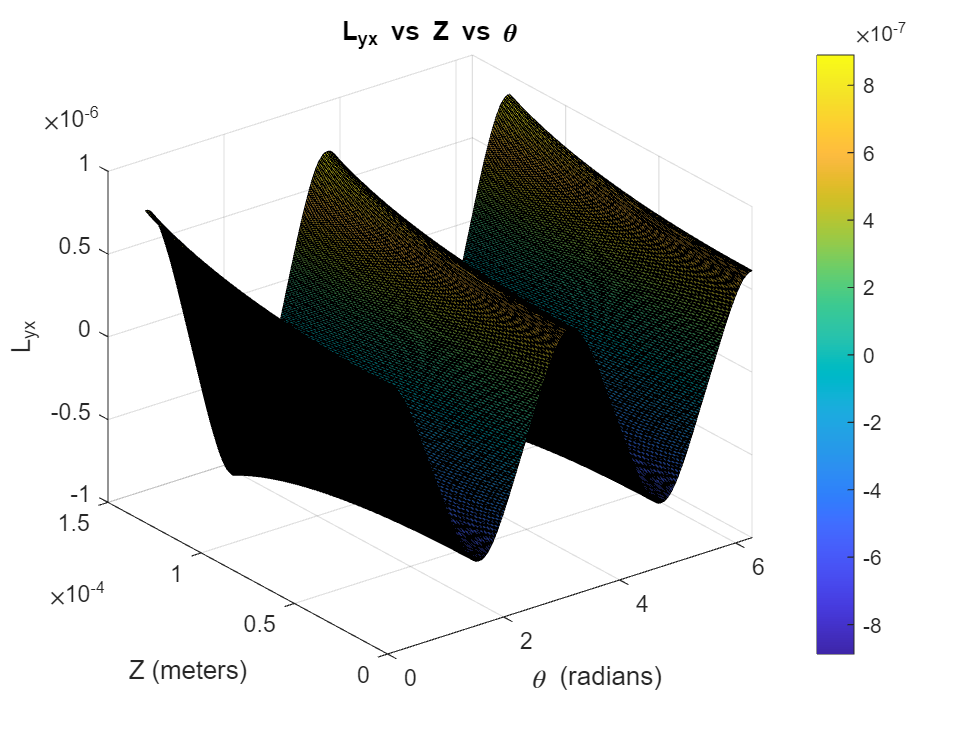


% plot_phi(phi, s_w, '\phi', 'n_{si}(\phi)');
% plot_phi(phi, nri_list(1, :), '\phi', 'n_{ri}(\phi)');
% plot_phi_for_each_z(phi, G, 'Phi (rad)', 'g (m)');

[Z, Phi] = meshgrid(z, phi);
% plot_surf(Phi, Z, G_for_z, 'Phi (radians)', 'Z (meters)', 'G (meters)', 'G vs Phi vs Z');

% plot_surf(Z, Phi, turns_phases{2, 1}, 'Z (meters)', '\phi (radians)', 'Winding Function', 'L_{yx} vs Z vs \theta');
% plot_surf(Z, Phi, winding_phases{1, 1}, 'Z (meters)', '\phi (radians)', 'Winding Function', 'L_{yx} vs Z vs \theta');
% plot_surf(Z, Phi, winding_phases{2, 1}, 'Z (meters)', '\phi (radians)', 'Winding Function', 'L_{yx} vs Z vs \theta');

[Z_i, Theta] = meshgrid(z, theta_r);
 plot_surf(Theta, Z_i, squeeze(Lxy_mat(1,4 , :, :)), '\theta (radians)', 'Z (meters)', 'L_{yx}', 'L_{yx} vs Z vs \theta');

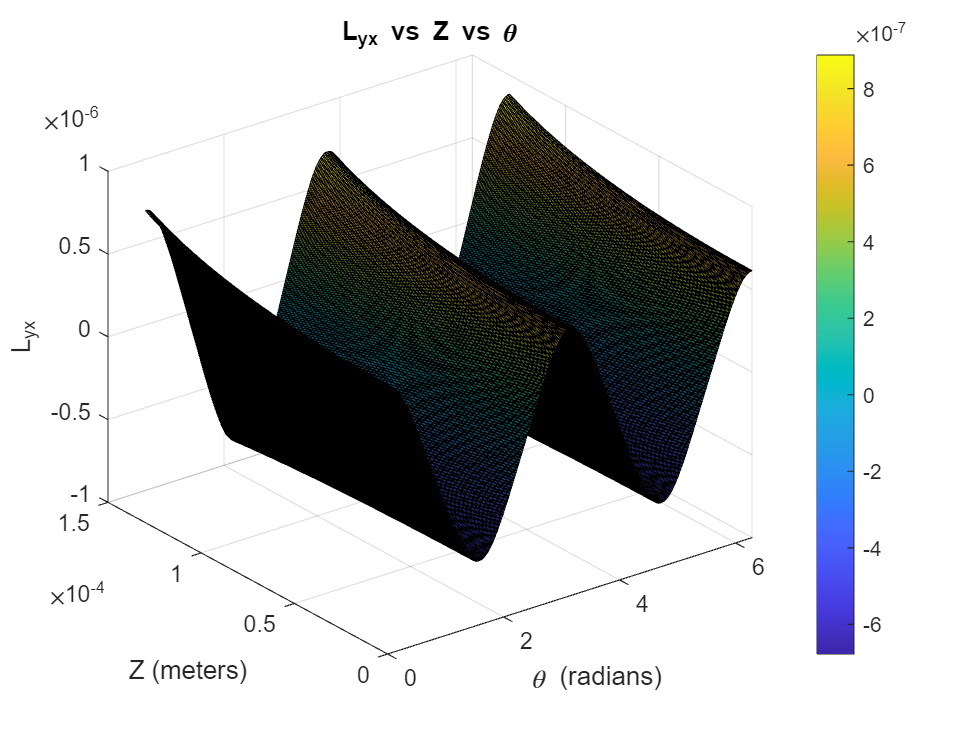


 plot_surf(Theta, Z_i, squeeze(Lxy_mat(4,1 , :, :)), '\theta (radians)', 'Z (meters)', 'L_{yx}', 'L_{yx} vs Z vs \theta');

% % plot(Theta, L_yx,'red')
% ylabel('L_{yx}');
% xlabel('\theta (radians)');
% title('Inductance at end of Stack Length')

% plot_surf(Theta, Z_i, Lxy{6, 1}, '\theta (radians)', 'Z (meters)', 'L_{yx}', 'L_{yx} vs Z vs \theta');
% % plot(Theta, L_yx,'red')
% ylabel('L_{yx}');
% xlabel('\theta (radians)');
% title('Inductance at end of Stack Length')



function s_t = stator_turns(phi, h_size, i, no_st_turns)
s_t = ((38*no_st_turns)/15)*ones(size(phi));
for h = 1:h_size
    sum1 = (((no_st_turns)/(pi*h)) * (cos(2*h*(phi-(((i-1)*pi)/3))))) *((2*sin((2*h*pi)/5) + (2*sin((2*h*4*pi)/15)) - (2*sin((2*h*11*pi)/15)) - (2*sin((2*h*4*pi)/5)) + (sin((2*h*pi)/3)) - (sin((2*2*h*pi)/3))));
    sum2 = (((no_st_turns)/(pi*h)) * (sin(2*h*(phi-(((i-1)*pi)/3))))) * ((5 - (2*cos((2*h*pi)/5)) - (2*cos((2*h*4*pi)/15)) + (2*cos((2*h*11*pi)/15)) + (2*cos((2*h*4*pi)/5)) - (cos(2*h*pi/3)) + (cos((2*2*h*pi)/3)) - (5*cos(2*h*pi))));
    s_t = (s_t + sum1 + sum2)  ;
end
end

function r_t = rotor_turns(phi, theta, no_rt_turns, j, h_size)
r_t = 0;
for h = 1:h_size
    sum1 = (((no_rt_turns)/(pi*h)) * (cos(2*h*(phi- theta-(((j-1)*pi)/3))))) *((sin((h*pi)/3) + (2*sin((h*pi)/2)) + (sin((2*h*pi)/3)) - (2*sin((h*3*pi)/2)) - (sin((4*h*pi)/3)) - (sin((5*h*pi)/3))));
    sum2 = (((no_rt_turns)/(pi*h)) * (sin(2*h*(phi-theta-(((j-1)*pi)/3))))) * ((4 - (cos((h*pi)/3)) - (2*cos((h*pi)/2)) - (cos((2*h*pi)/3)) +(2*cos((3*h*pi)/2))+ (cos((h*4*pi)/3)) + (cos(5*h*pi/3)) - (4*cos(2*h*pi))));
    r_t = (r_t + sum1 + sum2 );
end
r_t = r_t + (2*no_rt_turns);
end

function [s_w_temp, r_w_temp, L_yx_temp, int_n_over_g_sum_s, g_avg_sum_s, int_n_over_g_sum_r, g_avg_sum_r] = initialize_arrays()
s_w_temp = zeros(3, 1);
r_w_temp = zeros(3, 1);
L_yx_temp = zeros(3, 1);
int_n_over_g_sum_s = zeros(3, 1);
g_avg_sum_s = zeros(3, 1);
int_n_over_g_sum_r = zeros(3, 1);
g_avg_sum_r = zeros(3, 1);
end

function [turns_phase_selected, winding_phase_selected] = select_phases(i, j, t_i, i_z, turns_phases, winding_phases)
    j_t = mod(i, 3) + 1;
    j_w = mod(j, 3) + 1;
    if i > 2
        % Select rotor turns (i_w = 2)
        i_t = 2;
        turns_phase_selected = turns_phases{i_t, j_t}(t_i, :);
    else
        % Select stator turns (i_w = 2)
        i_t = 1;
        turns_phase_selected = turns_phases{i_t, j_t};
    end
    if j > 2
        % Select rotor winding (i_w = 2)
        i_w = 2;
        winding_phase_selected = winding_phases{i_w, j_w}(t_i, :);
    else
        %Select stator winding (i_w = 1)
        i_w = 1;
        winding_phase_selected = winding_phases{i_w, j_w}(:, i_z)';
    end
end


function [turns_func_avg, int_n_over_g_sum, g_avg_sum] = winding_function(func, G, phi, dz, L, g_avg_sum, int_n_over_g_sum)
int_n_over_g = dz*trapz( phi, func ./ G);
int_n_over_g_sum =  (int_n_over_g_sum + int_n_over_g);
g_inv = 1./G;
g_avg = dz*(1/(2*pi*L))*trapz( phi, g_inv);
g_avg_sum =( g_avg_sum+ g_avg);
turns_func_avg = (1/(2*pi*L*g_avg_sum))*int_n_over_g_sum;
end

function plot_phi(phi, data, xlabel_text, ylabel_text)
plot(phi, data);
xlabel(xlabel_text);
ylabel(ylabel_text);
xticks([0, pi, 2*pi]);
xticklabels({'0', '\pi', '2\pi'});
grid on;
end


function plot_surf(x, y, z, xlabel_text, ylabel_text, zlabel_text, title_text)
figure;
surf(x, y, z);
xlabel(xlabel_text);
ylabel(ylabel_text);
zlabel(zlabel_text);
title(title_text);
colorbar;
end


